# **Κεφάλαιο 1: Ταξινομητές που βασίζονται στη θεωρία αποφάσεων του Bayes**

*Τα παραδείγματα και οι ασκήσεις που περιλαμβάνονται στο παρόν σημειωματάριο, βρίσκονται στο βιβλίο: Theodoridis S., Pikrakis A., Koutroumbas K., Cavouras D., Εισαγωγή στην Αναγνώριση Προτύπων με MATLAB, Εκδόσεις Πασχαλίδης, 2011*

## **Η Gaussian συνάρτηση πυκνότητας πιθανότητας**

### Παράδειγμα 1

Να υπολογίσετε την τιμή της Gaussian σ.π.π. για τα παρακάτω σημεία:


$$$x_1=[0.2, 1.3]^T$$$
 
$$x_2=[2.2, -1.3]^T$$


με $m=[0,1]^T, 
S= \left[\matrix{ 1 & 0 \cr 0 &1} \right]$

close('all');
clear;

% Use function comp_gauss_dens_val to compute the value of the Gaussian pdf.
m=[0 1]'; S=eye(2);
x1=[0.2 1.3]'; x2=[2.2 -1.3]';
pg1=comp_gauss_dens_val(m,S,x1)

pg1 = 0.1491

pg2=comp_gauss_dens_val(m,S,x2)

pg2 = 0.0010

### Παράδειγμα 2

Θεωρήστε το πρόβλημα ταξινόμησης δύο κλάσεων στο διδιάστατο χώρο, όπου τα δεδομένα και στις δύο κλάσεις $\omega_1, \omega_2$ ακολουθούν την κανονική κατανομή με στοιχεία:


$$m_1=[1,1]^T, m_2=[3,3]^T \\
S_1=S_2== \left[ \matrix{1 & 0 \cr 0 &1} \right]$$


Υποθέτοντας ότι $P(\omega_1)=P(\omega_2)=1/2$, να ταξινομήσετε το διάνυσμα $x=[1.8, 1.8]^T$ σε μια από τις δύο παραπάνω κατηγορίες.

% Utilize function comp_gauss_dens_val
P1=0.5;
P2=0.5;
m1=[1 1]'; 
m2=[3 3]'; 
S=eye(2); 
x=[1.8 1.8]';
p1=P1*comp_gauss_dens_val(m1,S,x)

p1 = 0.0420

p2=P2*comp_gauss_dens_val(m2,S,x)

p2 = 0.0189

*Από τα παραπάνω αποτελέσματα βλέπουμε ότι η πιθανότητα να ανήκει στην πρώτη κλάση, είναι μεγαλύτερη από αυτή που υπολογίζεται για την δεύτερη, συνεπώς ****το διάνυσμα ανήκει στην πρώτη κατηγορία****.*

### Άσκηση 1

Να επαναλάβετε το παραπάνω παράδειγμα χρησιμοποιώντας $P(\omega_1)=1/6,P(\omega_2)=5/6$ καθώς και για $P(\omega_1)=5/6,P(\omega_2)=1/6$. Παρατηρήστε ότι το αποτέλεσμα εξαρτάται από τις εκ των προτέρων (a priori) πιθανότητες.

% Utilize function comp_gauss_dens_val
P1=5/6;
P2=1/6;
m1=[1 1]'; 
m2=[3 3]'; 
S=eye(2); 
x=[1.8 1.8]';
p1=P1*comp_gauss_dens_val(m1,S,x)

p1 = 0.0699

p2=P2*comp_gauss_dens_val(m2,S,x)

p2 = 0.0063

### Παράδειγμα 3

Δημιουργήστε $N=500$ διδιάστατα σημεία δεδομένων που υπακούουν στην Gaussian κατανομή με μέση τιμή $m=[0, 0]^T$και πίνακα συνδιασποράς $S=\left[ \matrix{\sigma_1^2 & \sigma_{12} \cr \sigma_{12} 
 & \sigma_2^2} \right]$, για τις παρακάτω διαφορετικές περιπτώσεις:


$$\sigma_1^2=\sigma_2^2=1, \sigma_{12}=0 \\
\sigma_1^2=\sigma_2^2=0.2, \sigma_{12}=0 \\
\sigma_1^2=\sigma_2^2=2, \sigma_{12}=0 \\
\sigma_1^2=0.2, \sigma_2^2=2, \sigma_{12}=0 \\
\sigma_1^2=2,\sigma_2^2=0.2, \sigma_{12}=0 \\
\sigma_1^2=\sigma_2^2=1, \sigma_{12}=0.5 \\
\sigma_1^2=0.3,\sigma_2^2=2, \sigma_{12}=0.5 \\
\sigma_1^2=0.3,\sigma_2^2=2, \sigma_{12}=-0.5
$$


Να γίνει η γραφική παράσταση του κάθε συνόλου δεδομένων και να σχολιαστεί το σχήμα των ομάδων που δημιουργούνται από τα σημεία των δεδομένων.

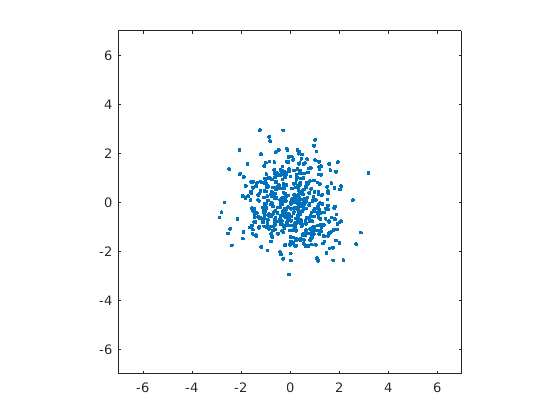

% Generate the first dataset (case #1)
randn('seed',0);
m=[0 0]';
S=[1 0;0 1];
N=500;
X = mvnrnd(m,S,N)';
% Plot the first dataset
figure(1), plot(X(1,:),X(2,:),'.');
figure(1), axis equal
figure(1), axis([-7 7 -7 7])

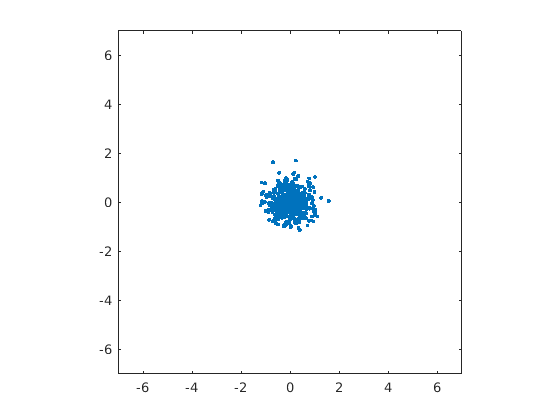


% Generate and plot the second dataset (case #2)
m=[0 0]';
S=[0.2 0;0 0.2];
N=500;
X = mvnrnd(m,S,N)';
figure(2), plot(X(1,:),X(2,:),'.');
figure(2), axis equal
figure(2), axis([-7 7 -7 7])

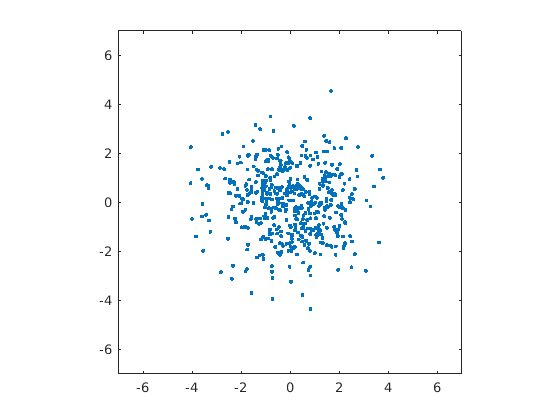


% Generate and plot the third dataset (case #3)
m=[0 0]';
S=[2 0;0 2];
N=500;
X = mvnrnd(m,S,N)';
figure(3), plot(X(1,:),X(2,:),'.');
figure(3), axis equal
figure(3), axis([-7 7 -7 7])

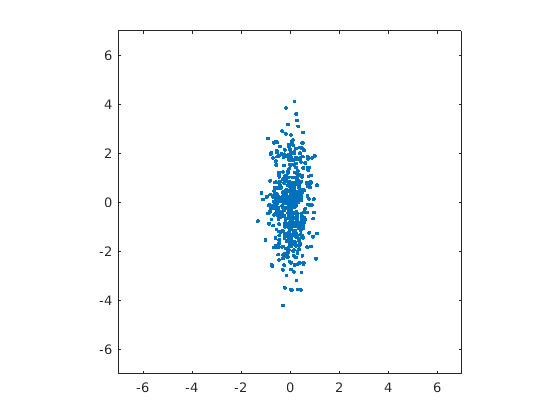


% Generate and plot the fourth dataset (case #4)
m=[0 0]';
S=[0.2 0;0 2];
N=500;
X = mvnrnd(m,S,N)';
figure(4), plot(X(1,:),X(2,:),'.');
figure(4), axis equal
figure(4), axis([-7 7 -7 7])

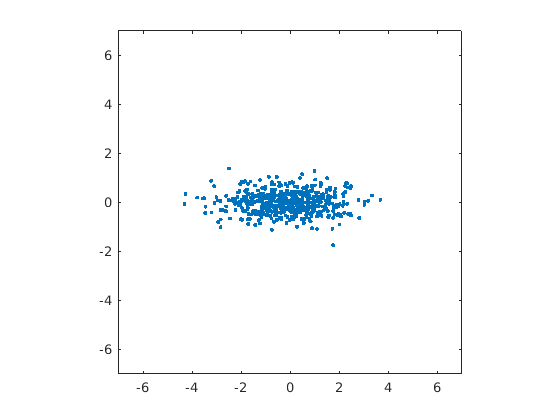


% Generate and plot the fifth dataset (case #5)
m=[0 0]';
S=[2 0;0 0.2];
N=500;
X = mvnrnd(m,S,N)';
figure(5), plot(X(1,:),X(2,:),'.');
figure(5), axis equal
figure(5), axis([-7 7 -7 7])

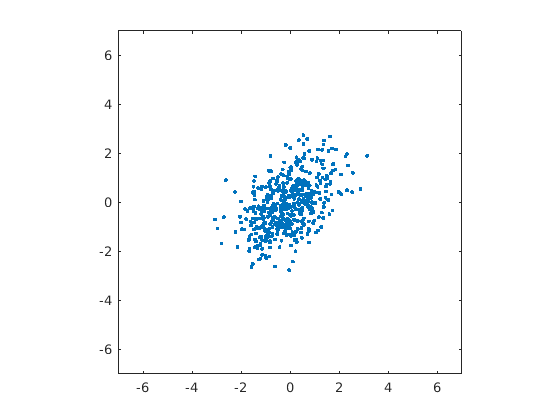


% Generate and plot the sixth dataset (case #6)
m=[0 0]';
S=[1 0.5;0.5 1];
N=500;
X = mvnrnd(m,S,N)';
figure(6), plot(X(1,:),X(2,:),'.');
figure(6), axis equal
figure(6), axis([-7 7 -7 7])

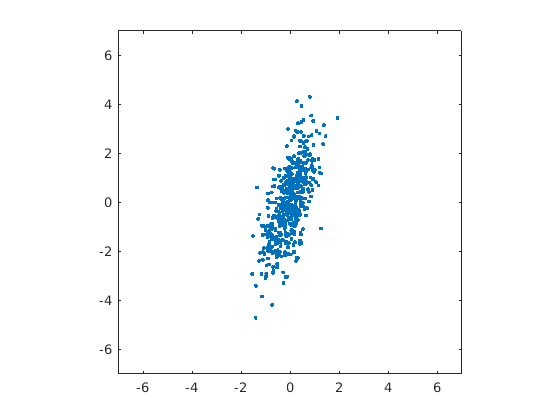


% Generate and plot the seventh dataset (case #7)
m=[0 0]';
S=[.3 0.5;0.5 2];
N=500;
X = mvnrnd(m,S,N)';
figure(7), plot(X(1,:),X(2,:),'.');
figure(7), axis equal
figure(7), axis([-7 7 -7 7])

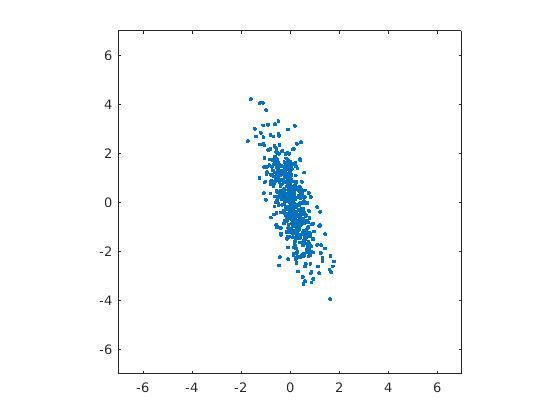


% Generate and plot the eighth dataset (case #8)
m=[0 0]';
S=[.3 -0.5;-0.5 2];
N=500;
X = mvnrnd(m,S,N)';
figure(8), plot(X(1,:),X(2,:),'.');
figure(8), axis equal
figure(8), axis([-7 7 -7 7])

## **Ταξινομητές ελάχιστης απόστασης**

### Παράδειγμα 1

Έστω ένα πρόβλημα ταξινόμησης σε δύο κλάσεις στον τρισδιάστατο χώρο, όπου οι κλάσεις $\omega_1, \omega_2$ μοντελοποιούνται με Gaussian κατανομές με μέσες τιμές $m_1=[0, 0, 0]^T$ και $m_2=[0,5, 0,5, 0,5]^T$ αντίστοιχα. Υποθέστε ότι οι δύο κλάσεις είναι ισοπίθανες. Το κοινό μητρώο συνδιασποράς είναι ίσο με:


$$S=\left[ \matrix{0.8 & 0.01 & 0.01 \cr 0.01 & 0.2 & 0.01 \cr 0.01 & 0.01 & 0.2} \right]$$


Να ταξινομηθεί το σημείο $x=[0.1, 0.5, 0.1]^T$ σύμφωνα με:

- τον ταξινομητή Ευκλείδειας απόστασης

- τον ταξινομητή Mahalanobis απόστασης.

Να σχολιάσετε τα αποτελέσματα που προκύπτουν.


% 1. Utilize function euclidean_classifier by typing
x=[0.1 0.5 0.1]';
m1=[0 0 0]'; 
m2=[0.5 0.5 0.5]';
m=[m1 m2];

z = 1

de =     0.5196    0.5657


[z,de]=euclidean_classifier(m,x)


**Παρατηρούμε ότι σε αυτή την περίπτωση, η ταξινόμηση γίνεται στην κλάση **$\omega_1$

% 2. Use function mahalanobis_classifier
x=[0.1 0.5 0.1]';
m1=[0 0 0]'; 
m2=[0.5 0.5 0.5]';
m=[m1 m2];
S=[0.8 0.01 0.01;
   0.01 0.2 0.01; 
   0.01 0.01 0.2];

z = 2

dm =     1.1334    0.9918


[z,dm]=mahalanobis_classifier(m,S,x)

**Παρατηρούμε ότι σε αυτή την περίπτωση, η ταξινόμηση γίνεται στην κλάση **$\omega_2$

## Εκτίμηση Μέγιστης Πιθανοφάνειας των Παραμέτρων της Gaussian Συνάρτησης Πυκνότητας Πιθανότητας

### Παράδειγμα 1

Να δημιουργήσετε 50 διδιάστατα διανύσματα χαρακτηριστικών που υπακούουν σε μια Gaussian κατανομή με χαρακτηριστικά:


$$m=[2,-2]^T \\
S= \left[ \matrix{0.9 & 0.2 \cr 0.2 & 0.3} \right]$$


Αν τα χαρακτηριστικά τα αποθηκεύσετε σε έναν πίνακα $X$ (κάθε στήλη και ένα διάνυσμα χαρακτηριστικών), να υπολογίσετε την εκτίμηση Μέγιστης Πιθανοφάνειας της μέσης τιμής  $m$ και του μητρώου συνδιασποράς $S$ της κανονικής κατανομής και να σχολιάσετε της εκτιμήσεις που προκύπτουν.

% Generate dataset X
randn('seed',0);
m = [2 -2]; S = [0.9 0.2; 0.2 .3];
X = mvnrnd(m,S,50)';

% Compute the ML estimates of m and S

m_hat =     2.0495
   -1.9418


S_hat =     0.8082    0.0885
    0.0885    0.2298


[m_hat, S_hat]=Gaussian_ML_estimate(X)


Παρατηρούμε ότι τα αποτελέσματα παρόλο που είναι κοντά στις αρχικές τιμές των παραμέτρων της κανονικής κατανομής, δεν μπορούν να γίνουν αποδεκτά ως αξιόπιστα. Ο λόγος είναι ο μικρός αριθμός των σημείων που έχουμε πάρει για την εκτίμηση.

### Άσκηση 1

Να επαναλάβετε το προηγούμενο παράδειγμα θεωρώντας $N=500$ σημεία καθώς και $N=5000$ σημεία. Να σχολιάσετε τα αποτελέσματα.

### Παράδειγμα 2

Να δημιουργήσετε δύο σύνολα δεδομένων: Το σύνολο $X$ (σύνολο εκπαίδευσης) και το σύνολο $X_1$ (σύνολο δοκιμής), κάθε ένα από τα οποία αποτελείται από $N=1000$ τρισδιάστατα διανύσματα που πηγάζουν από τρεις ισοπίθανες κλάσεις, τις $\omega_1, \omega_2, \omega_3$. Οι κλάσεις μοντελοποιούνται με Gaussian κατανομές, με μέσες τιμές $m_1=[0,0,0]^T$, $m_2=[1,2,2]^T$ και $m_3=[3,3,4]^T$ αντιστοίχως και μητρώα συνδιασποράς


$$S_1=S_2=S_3=\left[  \matrix{0.8 & 0 & 0 \cr 0 & 0.8 & 0 \cr 0 & 0 & 0.8} \right]=\sigma^2I$$


- Χρησιμοποιώντας το σύνολο $X$ να υπολογίσετε την εκτίμηση ΜΠ των μέσων τιμών και των μητρώων συνδιασποράς των κατανομών των τριών κλάσεων. Επειδή γνωρίζουμε ότι το μητρώο είναι ίδιο και για τις τρεις κλάσεις, να εκτιμήσετε ξεχωριστά για κάθε μια περίπτωση και στο τέλος να υπολογίσετε το μέσο μητρώο των τριών εκτιμήσεων σας.

- Να χρησιμοποιήσετε τον ταξινομητή Ευκλείδιας απόστασης για την ταξινόμηση των σημείων του συνόλου $X_1$ αξιοποιώντας τις εκτιμήσεις από την προηγούμενη απάντηση σας

- Να χρησιμοποιήσετε τον ταξινομητή Mahalanobis απόστασης για να ταξινομήσετε τα σημεία του συνόλου $X_1$, βασιζόμενοι και πάλι στις εκτιμήσεις ΜΠ που υπολογίσατε στο ερώτημα (1)

- Να χρησιμοποιήσετε τον Bayesian ταξινομητή για την ταξινόμηση των σημείων του συνόλου $X_1$, με βάση και πάλι τις εκτιμήσεις ΜΠ.

- Για κάθε περίπτωση από τις 3 παραπάνω να υπολογίσετε την πιθανότητα λάθους και να συγκρίνετε τα αποτελέσματα.

clear all ; 
% To generate X, utilize the function generate_gauss_classes
m=[0 0 0; 1 2 2; 3 3 4]';
S1=0.8*eye(3);
S(:,:,1)=S1; S(:,:,2)=S1; S(:,:,3)=S1;
P=[1/3 1/3 1/3]'; 
N=1000;
randn('seed',0);
[X,y]=generate_gauss_classes(m,S,P,N);

% The data set X1 is generated similarly
randn('seed',100);
[X1,y1]=generate_gauss_classes(m,S,P,N);

% 1. Compute the ML estimates of the mean values and covariance matrix (common to all three
% classes) using function Gaussian_ML_estimate
class1_data=X(:,find(y==1));
[m1_hat, S1_hat]=Gaussian_ML_estimate(class1_data);
class2_data=X(:,find(y==2));
[m2_hat, S2_hat]=Gaussian_ML_estimate(class2_data);
class3_data=X(:,find(y==3));
[m3_hat, S3_hat]=Gaussian_ML_estimate(class3_data);
S_hat=(1/3)*(S1_hat+S2_hat+S3_hat);
m_hat=[m1_hat m2_hat m3_hat];

% 2. Employ the Euclidean distance classifier, using the ML estimates of the means, in order to
% classify the data vectors of X1
z_euclidean=euclidean_classifier(m_hat,X1);

% 3. Similarly, for the Mahalanobis distance classifier, we have
z_mahalanobis=mahalanobis_classifier(m_hat,S_hat,X1);

% 4. For the Bayesian classifier, use function bayes classifier and provide as input the matrices

err_euclidean = 0.0761

% m, S, P, which were used for the dataset generation.

err_mahalanobis = 0.0771

z_bayesian=bayes_classifier(m,S,P,X1);

err_bayesian = 0.0761


% 5. Compute the error probability for each classifier
err_euclidean = (1-length(find(y1==z_euclidean))/length(y1))
err_mahalanobis = (1-length(find(y1==z_mahalanobis))/length(y1))
err_bayesian = (1-length(find(y1==z_bayesian))/length(y1))


Οι πιθανότητες λάθους για κάθε έναν από τους παραπάνω ταξινομητές είναι $7.61\%, 7.71\%, 7.61\%
$ αντίστοιχα. Αυτό δείχνει ότι οι 3 ταξινομητές είναι ισοδύναμοι.

### Άσκηση 2

Να επαναλάβετε το παραπάνω παράδειγμα χρησιμοποιώντας


$$S_1=S_2=S_3=\left[  \matrix{0.8 & 0.2 & 0.1 \cr 0.2 & 0.8 & 0.2 \cr 0.1 & 0.2 & 0.8} \right] \neq \sigma^2I$$


Να σχολιάσετε τα αποτελέσματα που προκύπτουν.

### Άσκηση 3

Να επαναλάβετε το προηγούμενο παράδειγμα χρησιμοποιώντας $P_1=1/2,P_2=P_3=1/4$ για τη δημιουργία των συνόλων $X$ και $X_1$.Επειδή σε αυτή την περίπτωση δεν είναι ίσες οι a priori πιθανότητες των κλάσεων, ο Bayesian ταξινομητής θα πρέπει να έχει καλύτερη απόδοση. Γιατί;

### Άσκηση 4

Να επαναλάβετε το προηγούμενο παράδειγμα για $P(\omega_1)=P(\omega_2)=P(\omega_3)=1/3$ και 


$$S_1=\left[ \matrix { 0.8 & 0.2 & 0.1 \cr 0.2 & 0.8 & 0.2 \cr 0.1 & 0.2 & 0.8} \right], S_2=\left[ \matrix { 0.6 & 0.01 & 0.01 \cr 0.01 & 0.8 & 0.01 \cr 0.01 & 0.01 & 0.6} \right], S_3=\left[ \matrix { 0.6 & 0.1 & 0.1 \cr 0.1 & 0.6 & 0.1 \cr 0.1 & 0.1 & 0.6} \right]$$


Να πειραματιστείτε με τις μέσες τιμές (πλησιάζοντας και απομακρύνοντας τις) καθώς και με τις a priori πιθανότητες. Να σχολιάσετε τα αποτελέσματα.

## Μοντέλα Μίξης

### Παράδειγμα 1

Θεωρήστε τη διδιάστατη συνάρτηση πυκνότητας πιθανότητας


$$p(x)=P_1p(x|1)+P2p(x|2)$$


όπου $p(x|j),j=1,2$ είναι κανονικές κατανομές με μέσες τιμές $m_1=[1,1]^T$ και $m_2=[3,3]^T$ και μητρώα συνδιασποράς


$$S_1=\left[ \matrix { \sigma_1^2 & \sigma_{12} \cr \sigma_{12} & \sigma_2^2} \right], S_2=\left[ \matrix { \sigma^2 & 0 \cr 0 & \sigma^2} \right]$$


με $\sigma_1^2=0.1, \sigma_2^2=0.2, \sigma_{12}=-0.08, \sigma^2=0.1$.

Να δημιουργήσετε και να σχεδιάσετε ένα σύνολο $X$ που να αποτελείται από $N=500$ σημεία που προέρχονται από την $p(x)$ για (i) $P_1=P_2=0.5$ (ii) $P_1=0.85,P_2=0.15$ και (iii) πειραματιστείτε μεταβάλλοντας τις παραμέτρους $\sigma_1^2, \sigma_2^2, \sigma_{12}, \sigma^2$ των μητρών συνδιασποράς καθώς και τις πιθανότητες μίξης $P_1, P_2$

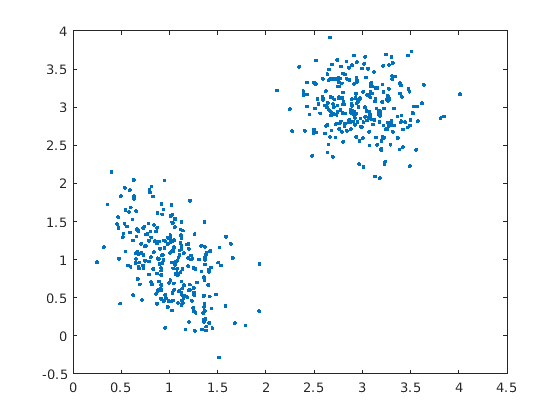

clear

% 1. To generate X, utilize the function mixt_model
randn('seed',0); 
m1=[1, 1]'; m2=[3, 3]';
m=[m1 m2];
S(:,:,1)=[0.1 -0.08; -0.08 0.2];
S(:,:,2)=[0.1 0; 0 0.1];
P=[1/2 1/2];

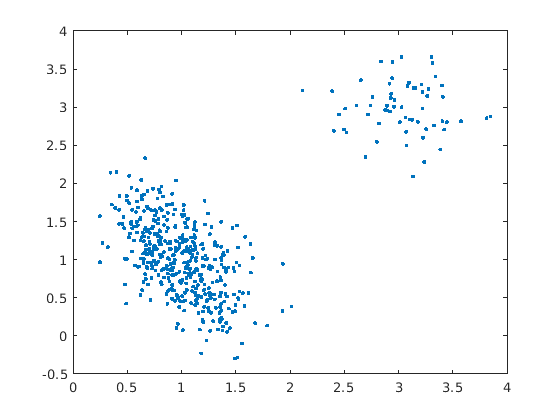

N=500;
sed=0; 
[X,y]=mixt_model(m,S,P,N,sed);
figure(1);
plot(X(1,:),X(2,:),'.');

% 2. Repeat step 1 for P1 = 0.85, P2 = 0.15.
randn('seed',0); 
m1=[1, 1]'; m2=[3, 3]';
m=[m1 m2];
S(:,:,1)=[0.1 -0.08; -0.08 0.2];
S(:,:,2)=[0.1 0; 0 0.1];
P=[0.85 0.15];

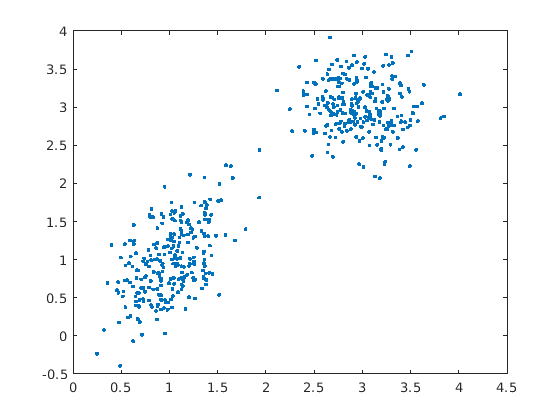

N=500;
sed=0; 
[X,y]=mixt_model(m,S,P,N,sed);
figure(2);
plot(X(1,:),X(2,:),'.');

% 3. Play by changing the parameters of the covariance matrices and the mixing probabilities P1 and P2.
randn('seed',0); 
m1=[1, 1]'; m2=[3, 3]';
m=[m1 m2];
S(:,:,1)=[0.1 0.08; 0.08 0.2];
S(:,:,2)=[0.1 0; 0 0.1];
P=[0.5 0.5];

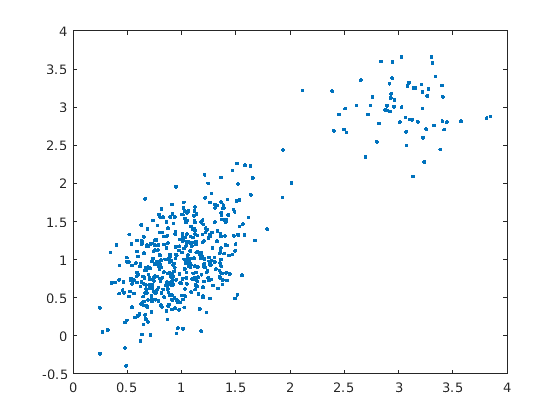

N=500;
sed=0; 
[X,y]=mixt_model(m,S,P,N,sed);
figure(3);
plot(X(1,:),X(2,:),'.');

randn('seed',0); 
m1=[1, 1]'; m2=[3, 3]';
m=[m1 m2];
S(:,:,1)=[0.1 0.08; 0.08 0.2];
S(:,:,2)=[0.1 0; 0 0.1];
P=[0.85 0.15];

N=500;
sed=0; 
[X,y]=mixt_model(m,S,P,N,sed);
figure(4);
plot(X(1,:),X(2,:),'.');

## Ο Expectation Maximization (EM) αλγόριθμος

### Παράδειγμα 1

Να δημιουργήσετε ένα σύνολο $X$ το οποίο αποτελείται από $N=500$ διδιάστατα σημεία που προέρχονται από την ακόλουθη σ.π.π


$$p(x)=\sum_{j=1}^3P_jp(x|j)$$


όπου $p(x|j),j=1,2,3$ είναι διδιάστατες κανονικές κατανομές με μέση τιμή $m_1=[1,1]^T,m_2=[3,3]^T, m_3=[2,6]^T$ και τα μητρώα συνδιασποράς $S_1=0.1I, S_2=0.2I, S_3=0.3I$ αντίστοιχα (με τον πίνακα $I$ να είναι ο μοναδιαίος $2X2$). Επιπλέον $P_1=0.4, P_2=0.4, P_3=0.2$.

Η βασική ιδέα είναι να χρησιμοποιήσουμε παραδείγματα που έχουν δημιουργηθεί με γνωστό τρόπο και να προσποιηθούμε ότι δεν γνωρίζουμε πως έχουν προκύψει. Θα υποθέσουμε ότι η σ.π.π. $p(x)$ που περιγράφει το σύνολο $X$ είναι ένα σταθμισμένο άθροισμα $J$ κανονικών κατανομών με μητρώα  συνδιασποράς της μορφής $S_i=\sigma_i^2I$ και θα χρησιμοποιήσουμε τον EM αλγόριθμο για να κάνουμε την εκτίμηση των άγνωστων παραμέτρων του μοντέλου που έχουμε υιοθετήσει για την $p(x)$. Στόχος του παραδείγματος αυτού είναι να αναδείξουμε την εξάρτηση του EM αλγορίθμου από τις αρχικές συνθήκες και την παράμετρο $J$. Για αυτό θα χρησιμοποιηθούν τα παρακάτω σύνολα αρχικών τιμών:

- 
$$J=3, m_{1,ini}=[0,2]^T, m_{2,ini}=[5,2]^T, m_{3,ini}=[5,5]^T, S_{1,ini}=0.15I, S_{2,ini}=0.27I, S_{3,ini}=0.4I, P_{1,ini}=P_{1,ini}=P_{1,ini}=1/3$$


- 
$$J=3, m_{1,ini}=[1.6,1.4]^T, m_{2,ini}=[1.4,1.6]^T, m_{3,ini}=[1.3,1.5]^T, S_{1,ini}=0.2I, S_{2,ini}=0.4I, S_{3,ini}=0.3I, P_{1,ini}=0.2, P_{1,ini}=0.4, P_{1,ini}=0.4$$


- 
$$J=2, m_{1,ini}=[1.6,1.4]^T, m_{2,ini}=[1.4,1.6]^T, S_{1,ini}=0.2I, S_{2,ini}=0.4I, P_{1,ini}=P_{1,ini}=1/2$$


Να σχολιάσετε τα αποτελέσματα

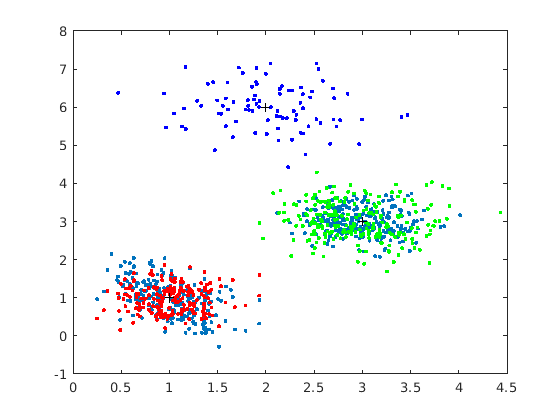

clear;

% Generate and plot dataset X
randn('seed',0);
m1=[1, 1]'; m2=[3, 3]';m3=[2, 6]';
m=[m1 m2 m3];

S(:,:,1)=0.1*eye(2);

S(:,:,2)=0.2*eye(2);
S(:,:,3)=0.3*eye(2);
P=[0.4 0.4 0.2];
N=500;
sed=0;
[X,y]=mixt_model(m,S,P,N,sed);
plot_data(X,y,m,1)


m_hat =     1.0213    0.9750
    2.9443    3.0224
    2.0250    6.0041


s_hat =     0.1047    0.2177    0.3044


Pa =     0.3877    0.4350    0.1773


iter = 12

Q_tot = 	1.0e+03 *

   -5.3552   -1.2883   -1.2256   -1.1643   -1.1073   -1.0684   -1.0626   -1.0625   -1.0625   -1.0625   -1.0625   -1.0625


e_tot =     8.6488    0.7303    0.8302    0.9277    0.7779    0.2659    0.0359    0.0050    0.0007    0.0001    0.0000    0.0000


% 1. Use function em_alg_function to estimate the mixture model parameters
m1_ini=[0; 2];m2_ini=[5; 2];m3_ini=[5; 5];
m_ini=[m1_ini m2_ini m3_ini];
s_ini=[.15 .27 .4];
Pa_ini=[1/3 1/3 1/3];
e_min=10^(-5);
[m_hat,s_hat,Pa,iter,Q_tot,e_tot]=em_alg_function(X,m_ini,s_ini,Pa_ini,e_min)

% 2. Work as in step 1
m1_ini=[1.6; 1.4];
m2_ini=[1.4; 1.6];
m3_ini=[1.3; 1.5];
m_ini=[m1_ini m2_ini m3_ini];

s_ini=[.2 .4 .3];
Pa_ini=[.2 .4 .4];
e_min=10^(-5);
[m_hat,s_hat,Pa,iter,Q_tot,e_tot]=em_alg_function(X,m_ini,s_ini,Pa_ini,e_min);

% 3. Work as in step 1
m1_ini=[1.6; 1.4];
m2_ini=[1.4; 1.6];
m_ini=[m1_ini m2_ini];

s_ini=[.2 .4 ];
Pa_ini=[.5 .5 ];
e_min=10^(-5);
[m_hat,s_hat,Pa,iter,Q_tot,e_tot]=em_alg_function(X,m_ini,s_ini,Pa_ini,e_min);


### Παράδειγμα 2

Θεωρήστε το σύνολο των δεδομένων $X$το οποίο αποτελείται από $N=1000$ διδιάστατα παραδείγματα.Τα 500 από αυτά προέρχονται από την πρώτη κλάση που μοντελοποιείται ως $p_1(x)=\sum_{j=1}^3 P_{1j}p(x|j), j=1,2,3$ με τις τρεις σ.π.π. να είναι κανονικές κατανομές με τις μέσες τιμές ίσες με $m_{11}=[1.25, 1.25]^T, m_{12}=[2.75, 2.75]^T, m_{13}=[2,6]^T$ και τα μητρώα συνδιασπορών $S_{ij}=\sigma_{1j}^2I,j=1,2,3$ όπου $\sigma_{11}^2=0.1, \sigma_{12}^2=0.2,\sigma_{13}^2=0.3$ αντιστίχως. Οι πιθανότητες μίξης είναι $P_{11}=0.4,P_{12}=0.4, P_{13}=0.2$.

Τα υπόλοιπα 500 διανύσματα δεδομένων προέρχονται από την κλάση $\omega_2$ η οποία μοντελοποιείται ως $p_2(x)=\sum_{j=1}^3 P_{2j}p(x|j), j=1,2,3$ με τις τρεις σ.π.π. να είναι κανονικές κατανομές με τις μέσες τιμές ίσες με $m_{21}=[1.25, 2.75]^T, m_{22}=[2.75, 1.25]^T, m_{23}=[4,6]^T$ και τα μητρώα συνδιασπορών $S_{ij}=\sigma_{2j}^2I,j=1,2,3$ όπου $\sigma_{21}^2=0.1, \sigma_{22}^2=0.2,\sigma_{23}^2=0.3$ αντιστίχως. Οι πιθανότητες μίξης είναι $P_{21}=0.4,P_{22}=0.3, P_{23}=0.5$.

Το σύνολο των δεδομένων θα χρησιμοποιηθεί ως σύνολο εκπαίδευσηγς και θα προσποιηθούμε ότι δεν γνωρίζουμε πως αυτό δημιουργήθηκε. Υποθέτουμε όμως ότι με κάποιο τρόπο έχουμε εκ των προτέρων γνώση σχετικά με το πλήθος των πυκνών περιοχών σε κάθε κλάση. Επομένως χρησιμοποιούμε ένα μοντέλο μίξης τριών Gaussian συνιστωσών για την μοντελοποίηση της σ.π.π. κάθε κλάσης. Το σύνολο των δεδομένων $X$ θα χρησιμοποιηθεί από τον αλγόριθμο EM για την εκτίμηση των "άγνωστων" παραμέτρων που υπεισέρχονται στα αντίστοιχα μοντέλα μίξης.

Κατόπιν, έχοντας υπολογίσει τις εκτιμήσεις των σ.π.π κάθε κλάσης, θα χρησιμοποιήσουμε τον Bayesian ταξινομητή. Για αυτόν τον λόγο θα δημιουργήσουμε ένα ακόμα σύνολο δεδομένων $Z$ με 1000 διανύσματα, τα μισά εκ των οποίων προέρχονται από την $p_1(x)$ και τα υπόλοιπα από την $p_2(x)$. Το σύνολο αυτό θα χρησιμοποιηθεί για να ελεγχθεί η απόδοση του ταξινομητή.

Χρησιμοποιήστε τον EM αλγόριθμο για να εκτιμήσετε τις $p_1(x), p_2(x)$ βασιζόμενοι στο σύνολο των δεδομένων $X$ και αρχικοποιώντας τις παραμέτρους ως εξής:

- για την $p_1(x)$: 3 κανονικές κατανομές με αρχικές μέσες τιμές $m_{11,ini}=[0,2]^T,m_{12,ini}=[5,2]^T, m_{13,ini}=[5,5]^T$, αρχικές εκτιμήσεις διασποράς $\sigma_{11,ini}^2=0.15, \sigma_{12,ini}^2=0.27, \sigma_{13,ini}^2=0.35$ και πιθανότητες μίξης $P_{11,ini}=P_{12,ini}=P_{13,ini}=1/3$

- για την $p_2(x)$: 3 κανονικές κατανομές με αρχικές μέσες τιμές $m_{21,ini}=[5,2]^T,m_{22,ini}=[3,4]^T, m_{23,ini}=[2,5]^T$, αρχικές εκτιμήσεις διασποράς $\sigma_{21,ini}^2=0.15, \sigma_{22,ini}^2=0.27, \sigma_{23,ini}^2=0.35$ και πιθανότητες μίξης $P_{21,ini}=P_{22,ini}=P_{23,ini}=1/3$

Με διαθέσιμες τις εκτιμήσεις των $p_1(x), p_2(x)$χρησιμοποιήστε τον κανόνα ταξινόμησης κατά Bayes προκειμένου να ταξινομήσετε τα διανύσματα του συνόλου $Z$. Υπολογίστε το σφάλμα ταξινόμησης.

clear;

% Generate the subset X1 of X, which contains the data points from the first class
m11=[1.25 1.25]'; m12=[2.75 2.75]';m13=[2 6]';
m1=[m11 m12 m13];
S1(:,:,1)=0.1*eye(2);
S1(:,:,2)=0.2*eye(2);
S1(:,:,3)=0.3*eye(2);
P1=[0.4 0.4 0.2];
N1=500;
sed=0;
[X1,y1]=mixt_model(m1,S1,P1,N1,sed);

% The subset X2 of X, with the points from the second class is generated similarly (use again sed = 0)
m21=[1.25 2.75]'; m22=[2.75 1.25]';m23=[4 6]';
m2=[m21 m22 m23];
S2(:,:,1)=0.1*eye(2);
S2(:,:,2)=0.2*eye(2);
S2(:,:,3)=0.3*eye(2);
P2=[0.2 0.3 0.5];
N2=500;
sed=0;
[X2,y2]=mixt_model(m2,S2,P2,N2,sed);

% Dataset Z is generated in two steps,i.e., 500 points are first generated from 
% the first class (dataset Z1)
mZ11=[1.25 1.25]'; mZ12=[2.75 2.75]';mZ13=[2 6]';
mZ1=[mZ11 mZ12 mZ13];
SZ1(:,:,1)=0.1*eye(2);
SZ1(:,:,2)=0.2*eye(2);
SZ1(:,:,3)=0.3*eye(2);
wZ1=[0.4 0.4 0.2];
NZ1=500;
sed=100;
[Z1,yz1]=mixt_model(mZ1,SZ1,wZ1,NZ1,sed);

% The remaining 500 points from the second class (dataset Z2) are generated similarly (use
% again sed = 100).
mZ21=[1.25 2.75]'; mZ22=[2.75 1.25]';mZ23=[4 6]';
mZ2=[mZ21 mZ22 mZ23];
SZ2(:,:,1)=0.1*eye(2);
SZ2(:,:,2)=0.2*eye(2);
SZ2(:,:,3)=0.3*eye(2);
wZ2=[0.2 0.3 0.5];
NZ2=500;
sed=100;
[Z2,yz2]=mixt_model(mZ2,SZ2,wZ2,NZ2,sed);

% Generate dataset Z
Z=[Z1 Z2];

% 1. Estimate the Gaussian mixture model of each class
m11_ini=[0; 2]; m12_ini=[5; 2]; m13_ini=[5; 5];
m1_ini=[m11_ini m12_ini m13_ini];
S1_ini=[0.15 0.27 0.4];
w1_ini=[1/3 1/3 1/3];
m21_ini=[5; 2]; m22_ini=[3; 4]; m23_ini=[2; 5];
m2_ini=[m21_ini m22_ini m23_ini];
S2_ini=[0.15 0.27 0.35];
w2_ini=[1/3 1/3 1/3];

m_ini{1}=m1_ini;
m_ini{2}=m2_ini;
S_ini{1}=S1_ini;
S_ini{2}=S2_ini;
w_ini{1}=w1_ini;
w_ini{2}=w2_ini;
[m_hat,S_hat,w_hat,P_hat]=EM_pdf_est([X1 X2],[ones(1,500) 2*ones(1,500)],m_ini,S_ini,w_ini);

% 2. Use function mixture_Bayes to classify the data vectors of Z and function compute_error to
% obtain the classification error.
for j=1:2
    le=length(S_hat{j});

classification_error = 0.0420

    te=[];
    for i=1:le
        te(:,:,i)=S_hat{j}(i)*eye(2);
    end
    S{j}=te;
end
[y_est]=mixture_Bayes(m_hat,S,w_hat,P_hat,Z);
[classification_error]=compute_error([ones(1,500) 2*ones(1,500)],y_est)


Υπολογίσαμε ότι το σφάλμα ταξινόμησης που προκύπτει είναι $4.20\%$

**Σχόλιο: **Στην πράξη, σε προβλήματα ταξινόμησης, όταν δεν είναι γνωστό το πλήθος των όρων που αθροίζονται σε ένα μοντέλο μίξης, επαναλαμβάνουμε τον EM αλγόριθμο αρκετές φορές με διαφορετικές τιμές της παραμέτρου $J$ και υιοθετούμε την τιμή της $J$ που έδωσε το μικρότερο σφάλμα ταξινόμησης για το σύνολο δοκιμής.

### Άσκηση 1

Να επαναλάβετε το παραπάνω παράδειγμα χρησιμοποιώντας σύνολα $X_1, X_2, Z_1, Z_2$  σύμφωνα με τις παρακάτω περιπτώσεις αρχικοποίησης:

#### Περίπτωση 1

- για την $p_1(x)$: 3 κανονικές κατανομές με αρχικές μέσες τιμές $m_{11,ini}=[5,5]^T,m_{12,ini}=[5.5,5.5]^T, m_{13,ini}=[5,5]^T$, αρχικές εκτιμήσεις διασποράς $\sigma_{11,ini}^2=0.2, \sigma_{12,ini}^2=0.4, \sigma_{13,ini}^2=0.3$ και πιθανότητες μίξης $P_{11,ini}=0.2,P_{12,ini}=0.4,P_{13,ini}=0.4$

- για την $p_2(x)$: 3 κανονικές κατανομές με αρχικές μέσες τιμές $m_{21,ini}=[2,2]^T,m_{22,ini}=[1.98,1.98]^T, m_{23,ini}=[2.4,2.4]^T$, αρχικές εκτιμήσεις διασποράς $\sigma_{21,ini}^2=0.06, \sigma_{22,ini}^2=0.05, \sigma_{23,ini}^2=0.4$ και πιθανότητες μίξης $P_{21,ini}=0.8,P_{22,ini}=0.1,P_{23,ini}=0.1$

#### Περίπτωση 2

- για την $p_1(x)$: 3 κανονικές κατανομές με αρχικές μέσες τιμές $m_{11,ini}=[1.6,1.4]^T,m_{12,ini}=[1.4,1.6]^T, m_{13,ini}=[1.3,1.5]^T$, αρχικές εκτιμήσεις διασποράς $\sigma_{11,ini}^2=0.2, \sigma_{12,ini}^2=0.4, \sigma_{13,ini}^2=0.3$ και πιθανότητες μίξης $P_{11,ini}=0.2,P_{12,ini}=0.4,P_{13,ini}=0.4$

- για την $p_2(x)$: 3 κανονικές κατανομές με αρχικές μέσες τιμές $m_{21,ini}=[1.5,1.7]^T,m_{22,ini}=[1.7,1.5]^T, m_{23,ini}=[1.6,1.6]^T$, αρχικές εκτιμήσεις διασποράς $\sigma_{21,ini}^2=0.6, \sigma_{22,ini}^2=0.05, \sigma_{23,ini}^2=0.02$ και πιθανότητες μίξης $P_{21,ini}=0.1,P_{22,ini}=0.8,P_{23,ini}=0.1$

#### Περίπτωση 3

- για την $p_1(x)$: 4 κανονικές κατανομές με αρχικές μέσες τιμές $m_{11,ini}=[0,2]^T,m_{12,ini}=[5,2]^T, m_{13,ini}=[5,5]^T, m_{14,ini}=[3,4]^T$, αρχικές εκτιμήσεις διασποράς $\sigma_{11,ini}^2=0.15, \sigma_{12,ini}^2=0.27, \sigma_{13,ini}^2=0.4, \sigma_{14,ini}^2=0.2$ και πιθανότητες μίξης $P_{11,ini}=P_{12,ini}=P_{13,ini}=P_{14,ini}=1/4$

- για την $p_2(x)$: 4 κανονικές κατανομές με αρχικές μέσες τιμές $m_{21,ini}=[1,2]^T,m_{22,ini}=[3.2,1.5]^T, m_{23,ini}=[1,4]^T, m_{24,ini}=[4,2]^T$, αρχικές εκτιμήσεις διασποράς $\sigma_{21,ini}^2=0.15, \sigma_{22,ini}^2=0.08, \sigma_{23,ini}^2=0.27, \sigma_{24,ini}^2=0.05$ και πιθανότητες μίξης $P_{21,ini}=P_{22,ini}=P_{23,ini}=P_{24,ini}=1/4$

#### Περίπτωση 4

- για την $p_1(x)$: 2 κανονικές κατανομές με αρχικές μέσες τιμές $m_{11,ini}=[0,2]^T,m_{12,ini}=[5,2]^T$, αρχικές εκτιμήσεις διασποράς $\sigma_{11,ini}^2=0.15, \sigma_{12,ini}^2=0.27$ και πιθανότητες μίξης $P_{11,ini}=P_{12,ini}=1/2$

- για την $p_2(x)$: 1 κανονική κατανομή με αρχική μέση τιμή $m_{21,ini}=[1,2]^T$, αρχική εκτίμηση διασποράς $\sigma_{21,ini}^2=0.15$ και πιθανότητα μίξης $P_{21,ini}=1$

#### Περίπτωση 5

- για την $p_1(x)$: 1 κανονική κατανομή με αρχική μέση τιμή $m_{11,ini}=[2,2]^T$, αρχική εκτίμηση διασποράς $\sigma_{11,ini}^2=0.4$και πιθανότητες μίξης $P_{11,ini}=1$

- για την $p_2(x)$: 1 κανονική κατανομή με αρχική μέση τιμή $m_{21,ini}=[1,2]^T$, αρχική εκτίμηση διασποράς $\sigma_{21,ini}^2=0.15$ και πιθανότητα μίξης $P_{21,ini}=1$

Για κάθε περίπτωση από τις παραπάνω, να σχολιάσετε τις εκτιμήσεις που επιστρέφει ο EM αλγόριθμος και να υπολογίσετε το σφάλμα ταξινόμησης του Bayesian ταξινομητή.

## Ο Naive Bayes ταξινομητής

### Παράδειγμα 1

Δημιουργήστε ένα σύνολο $X_1$ που αποτελείται από $N_1=50$ διδιάστατα διανύσματα δεδομένων, που πηγάζουν από δύο ισοπίθανες κλάσεις $\omega_1, \omega_2$. Οι κλάσεις μοντελοποιούνται από Gaussian κατανομές με μέσες τιμές $m_1=[0,0,0,0,0],m_2=[1,1,1,1,1]$ και μητρώα συνδιασποράς


$$S_1=\left[  \matrix{
0.8 & 0.2 & 0.1 & 0.05 & 0.01  \cr 
0.2 & 0.7 & 0.1 & 0.03 & 0.02  \cr 
0.1 & 0.1 & 0.8 & 0.02 & 0.01 \cr
0.05 & 0.03 & 0.02 & 0.9 & 0.01 \cr
0.01 & 0.02 & 0.01 & 0.01 & 0.8} \right],
S_2=\left[  \matrix{
0.9 & 0.1 & 0.05 & 0.02 & 0.01  \cr 
0.1 & 0.8 & 0.1 & 0.02 & 0.02  \cr 
0.05 & 0.1 & 0.7 & 0.02 & 0.01 \cr
0.02 & 0.02 & 0.02 & 0.6 & 0.02 \cr
0.01 & 0.02 & 0.01 & 0.02 & 0.7} \right]$$


Με όμοιο τρόπο, δημιουργήστε ένα σύνολο δεδομένων$X_2$ που αποτελείται από $N_2=10000$ σημεία. Το $X_1$ θα χρησιμοποιηθεί ως σύνολο εκπαίδευσης και το $X_2$ για δοκιμή.

Σύμφωνα με τον naive Bayes ταξινομητή, υποθέτουμε ότι για κάθε κλάση, τα χαρακτηριστικά στα διανύσματα δεδομένων είναι στατιστικώς ανεξάρτητα (παρόλο που αυτό γνωρίζουμε ότι δεν ισχύει), και ότι κάθε χαρακτηριστικό ακολουθεί μια μονοδιάστατη Gaussian κατανομή. Για κάθε μια από τις πέντε διαστάσεις, και για κάθε κλάση, υπολογίζουμε την εκτίμηση μέγιστης πιθανοφάνειας (i) των μέσων τιμών $m_{1j},m_{2j},j=1,2,\dots,5$ και (ii) των διασπορών $\sigma_{1j}^2,\sigma_{2j}^2,j=1,2,\dots,5$, χρησιμοποιώντας το σύνολο εκπαίδευσης $X_1$.

Για την επίλυση του παραπάνω προβλήματος ακολουθούμε τα παρακάτω βήματα:

(α) ταξινομούμε τα σημεία του συνόλου δοκιμής $X_2$ χρησιμοποιώντας τον naive Bayes ταξινομητή, όπου για δεδομένο $x$, η εκτίμηση της πιθανότητας $p(x|\omega_i)$ δίνεται από την:


$$p(x|\omega_i)=\prod_{j=1}^5\frac{1}{\sqrt{2\pi\sigma_{1j}^2}}exp\left( -\frac{(x(j)-m_{ij})^2}{2\sigma_{ij}^2}  \right),i=1,2$$


όπου $x(j)$είναι το $j$-οστό στοιχείο του $x$. Υπολογίζουμε την πιθανότητα λάθους.

(β) υπολογίζουμε την εκτίμηση μέγιστης πιθανοφάνειας των $m_1,m_2,S_1,S_2$ χρησιμοποιώντας το $X_1$. Εφαρμόζουμε τις εκτιμήσεις αυτές στον  Bayesian ταξινομητή που λειτουργεί στον $5-$διάστατο χώρο και υπολογίζουμε την νέα πιθανότητα λάθους.

(γ) συγκρίνουμε τα αποτελέσματα από τα βήματα (α) και (β)

clear;

% 1. Generate datasets X1 and X2
m=[zeros(5,1) ones(5,1)];
S(:,:,1)=[0.8 0.2 0.1 0.05 0.01;
          0.2 0.7 0.1 0.03 0.02;
          0.1 0.1 0.8 0.02 0.01;
          0.05 0.03 0.02 0.9 0.01;
          0.01 0.02 0.01 0.01 0.8];
S(:,:,2)=[0.9 0.1 0.05 0.02 0.01;
          0.1 0.8 0.1 0.02 0.02;
          0.05 0.1 0.7 0.02 0.01;
          0.02 0.02 0.02 0.6 0.02;
          0.01 0.02 0.01 0.02 0.7];
P=[1/2 1/2 ]'; N_1=100;
randn('state',0);
[X1,y1]=generate_gauss_classes(m,S,P,N_1);
N_2=10000;
randn('state',100);
[X2,y2]=generate_gauss_classes(m,S,P,N_2);

% Use function Gaussian_ML_estimate to compute the ML_estimate of the mean and
% variance per feature for each class (using set X1)
for i=1:5
    [m1_hat(i), S1_hat(i)]=Gaussian_ML_estimate(X1(i,find(y1==1)));
end
m1_hat=m1_hat'; S1_hat=S1_hat';
for i=1:5
    [m2_hat(i), S2_hat(i)]=Gaussian_ML_estimate(X1(i,find(y1==2)));
end
m2_hat=m2_hat'; S2_hat=S2_hat';

naive_error = 0.1320


% 2. Classify each point in X2 according to the naive Bayes classification scheme
for i=1:5
    perFeature1(i,:)=normpdf(X2(i,:),m1_hat(i),sqrt(S1_hat(i)));
    perFeature2(i,:)=normpdf(X2(i,:),m2_hat(i),sqrt(S2_hat(i)));
end
naive_probs1=prod(perFeature1);
naive_probs2=prod(perFeature2);
classified=ones(1,length(X2));
classified(find(naive_probs1<naive_probs2))=2;
% Compute the classification error
true_labels=y2;
naive_error=sum(true_labels~=classified)/length(classified)

% 3. Compute the maximum likelihood estimates of the “unknown” mean values and covariance
% matrices, m1, m2, S1 and S2, based on X1

Bayes_ML_error = 0.1426

[m1_ML, S1_ML]=Gaussian_ML_estimate(X1(:,find(y1==1)));
[m2_ML, S2_ML]=Gaussian_ML_estimate(X1(:,find(y1==2)));
% Classify the data vectors of X2 using the Bayesian classifier, which is based on the ML
% estimates of the respective parameters, type
m_ML(:,1)=m1_ML;
m_ML(:,2)=m2_ML;
S_ML(:,:,1)=S1_ML;
S_ML(:,:,2)=S2_ML;
P=[1/2 1/2];
z=bayes_classifier(m_ML,S_ML,P,X2);
% Compute the classification error, type
true_labels=y2;
Bayes_ML_error=sum(true_labels~=z)/length(z)

### Άσκηση 1

- Να ταξινομήσετε τα σημεία του συνόλου $X_2$ υιοθετώντας το βέλτιστο Bayesian ταξινομητή, δηλαδή να χρησιμοποιήσετε τις αληθινές μέσες τιμές και μητρώα συνδιασποράς που σχετίζονται με τις 5-διάστατες Gaussian σ.π.π. Να συγκρίνετε τα αποτελέσματα με αυτά του προηγούμενου παραδείγματος.

- Να επαναλάβετε το παραπάνω, θεωρώντας $X_1$ αποτελούμενο από $$N=1000$$ διανύσματα δεδομένων.

## Ταξινομητής πλησιέστερων γειτόνων

### Παράδειγμα 1

Έστω το πρόβλημα ταξινόμησης διδιάστατων χαρακτηριστικών, όπου τα δεδομένα πηγάζουν από δύο ισοπίθανες κλάσεις τις $\omega_1, \omega_2$. Οι κλάσεις μοντελοποιούνταιμε Gaussian κατανομές με μέσες τιμές $m_1=[0,0],m_2=[1,2]$ και μητρώα συνδιασποράς:


$$S_1=S_2=\left[  \matrix{0.8 & 0.2 \cr 0.2 & 0.8}  \right]$$


Δημιουργήστε δύο σύνολα δεδομένων $X_1,X_2$ που αποτελούνται από 1000 και 500 σημεία αντιστοίχως.

Θεωρώντας ότι $X_1$είναι το σύνολο εκπαίδευσης, ταξινομήστε τα σημεία του $X_2$ χρησιμοποιώντας τον k-NN ταξινομητή, για $k=3$ και υιοθετώντας ως μετρική απόστασης το τετράγωνο της Ευκλείδειας απόστασης. Υπολογίστε το σφάλμα ταξινόμησης.

clear;

% Generate datasets X1 and X2
m=[0 0; 1 2]';
S=[0.8 0.2;0.2 0.8];

pr_err = 0.1512

S(:,:,1)=S;S(:,:,2)=S;
P=[1/2 1/2 ]'; N_1=1000;
randn('seed',0);
[X1,y1]=generate_gauss_classes(m,S,P,N_1);
N_2=5000;
randn('seed',100);
[X2,y2]=generate_gauss_classes(m,S,P,N_2);

% For the classification task, use function k_nn_classifier (k=3)
k=3;
z=k_nn_classifier(X1,y1,k,X2);

% Compute the classification error
pr_err=sum(z~=y2)/length(y2)

### Άσκηση 1

Να επαναλάβετε το παράδειγμα για $k=1,7,15$. Για κάθε περίπτωση να υπολογίσετε το σφάλμα ταξινόμησης. Να συγκρίνετε τα αποτελέσματα με το λάθος του βέλτιστου Bayesian ταξινομητή, για τον οποίο θα χρησιμοποιηθούν οι αληθινές μέσες τιμές και μητρώο συνδιασποράς.